% Parameterize the arm
rho = 0.0254; % M, Radius

%% Construct pose matrices
% Transformations from world frame to each muscle

% Orientation of base curve (x = up):
R_g_o = eul2rotm([0, -pi/2, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(R_g_o, [0 0 0]); % Base-curve frame
g_muscles = Arm3D.generate_g_muscles(rho, g_o, 3, 0);

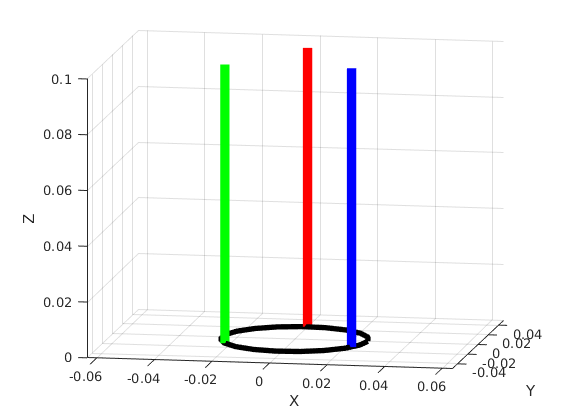

l_0 = 0.1;
spatial_arm_obj = Arm3D(g_o, g_muscles, l_0);

% Configure 3D Arm object
spatial_arm_obj.rho = rho;
spatial_arm_obj.n_circles = 4;

% Initialize plotting
fig = figure();
line_options_muscles = struct("LineWidth", 7);
line_options_circles = struct("LineWidth", 4);
spatial_arm_obj.initialize_plotting(axes(fig), ...
    "line_options_circles", line_options_circles, ...
    "line_options_muscles", line_options_muscles);
set(fig, 'Visible', true)

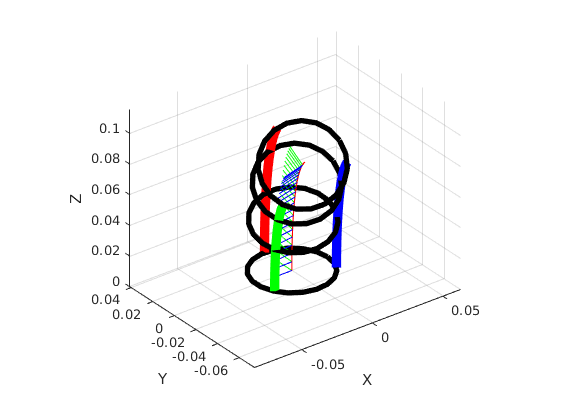

l_A = 0.13;
l_B = 0.09;
l_C = 0.11;
v_l = [l_A; l_B; l_C];

spatial_arm_obj.plot_base_curve = true;
h_o_tilde = spatial_arm_obj.update_arm(v_l);

t_end = 6;
fps = 30;
t = linspace(0, t_end, fps * t_end);

period = t_end;
l_max = 0.15;
%l_min = 0.17;
delta_l = 0.05;

l_A = l_max - delta_l * exp(-(t - 2).^2);
l_B = l_max - delta_l * exp(-(t - 3).^2);
l_C = l_max - delta_l * exp(-(t - 4).^2);

mat_l = [l_A(:) l_B(:) l_C(:)];

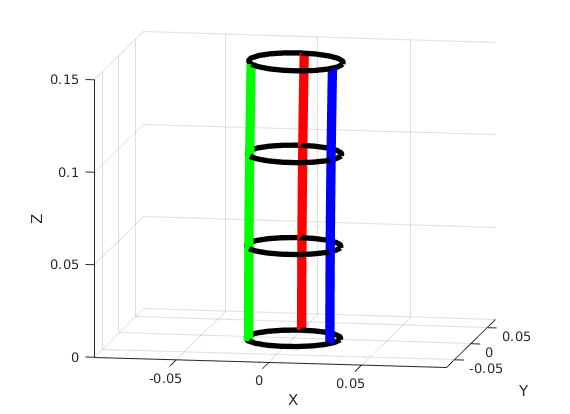

animator = Animator(fig, length(t));

for i = 1 : length(t)
    v_l_i = mat_l(i, :);
    spatial_arm_obj.update_arm(v_l_i(:));
    
    animator.get_frame();
    drawnow
end

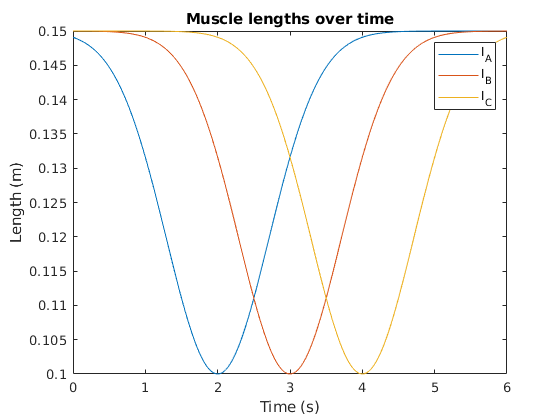

figure()
plot(t, mat_l);
legend(["l_A", "l_B", "l_C"])
title("Muscle lengths over time")
xlabel("Time (s)")
ylabel("Length (m)")

animator.save_gif("frame_rate", fps);